clear
close all
syms f(x)

L = 10;
b = 1;
h = 1;
A = b*h;
E = 10e6;
G = 3.846e6;
I = 1/12 * b * h^3;
k = 5/6;
f = x;

conditions = [3, 0, 0;...
              1, 0, 0;...
              0, L, 0;...
              1, L, 0;];
          
sol = computeExactSolution(L,E,I,k,A,G,f,conditions)

sol = struct with fields:
         f: [1×1 sym]
       eqn: [1×1 symfun]
      cond: [1×4 sym]
    domain: [0 1]
         U: [1×1 symfun]


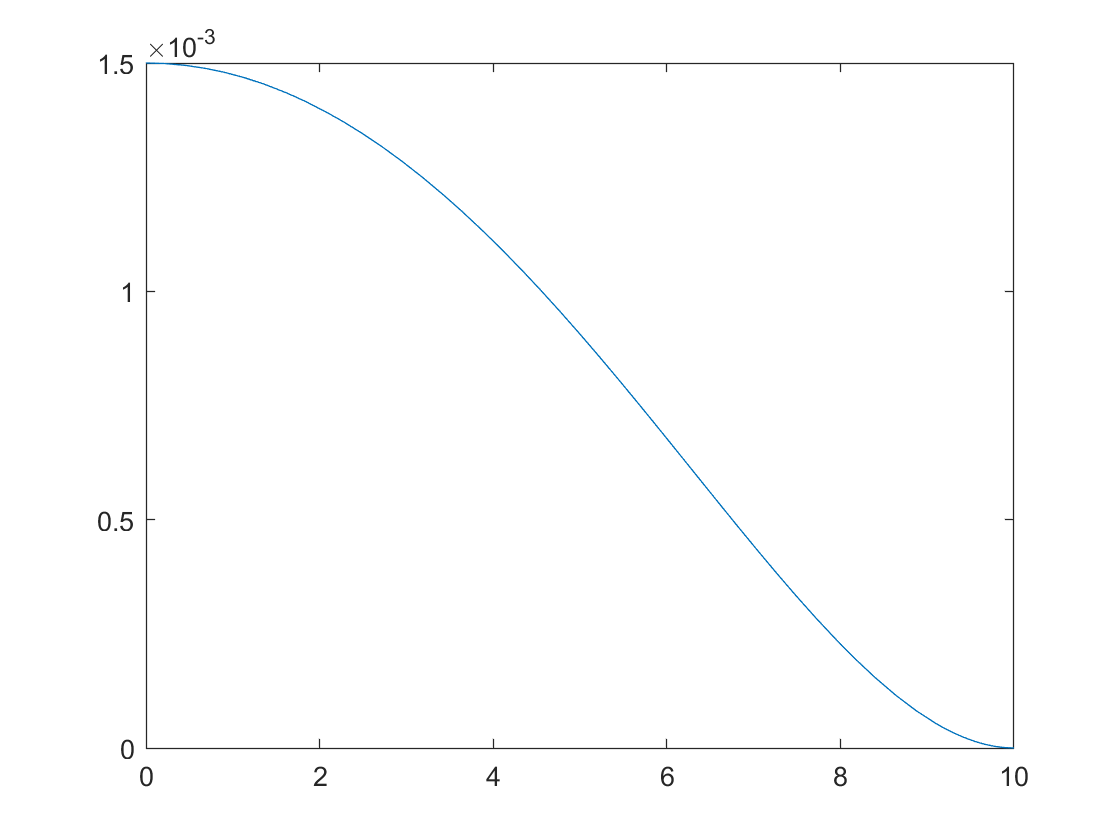

fplot(sol.U,[0,L])